## Power Consumption

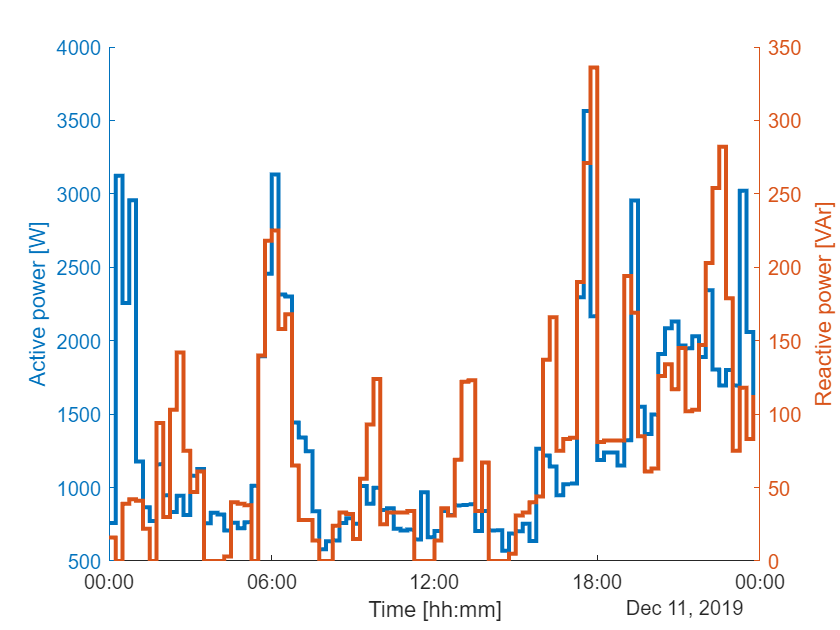

clc
clear
load("Consumption.mat")
figure()
hold on
yyaxis left
stairs(timestamp,P(:,3),LineWidth=2)
ylabel("Active power [W]")

yyaxis right
stairs(timestamp,Q(:,3),LineWidth=2)
ylabel("Reactive power [VAr]")
xlabel("Time [hh:mm]")

hold off
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/Consumption','epsc')

## Comparison plot illustration

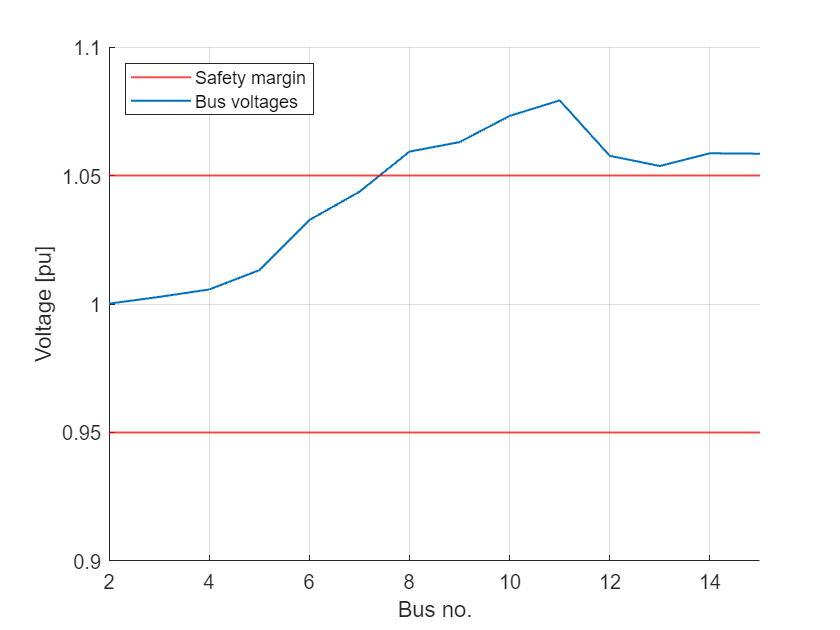

clc
clear
load("DataAndVariables\BaseDefinitions.mat")
addpath("Functions\")

measuredOutputs = [Psch(2:end,:) ;Qsch(2:end,:)];
[V, S] = NewRap(measuredOutputs(:,1));
busNo = linspace(2,15,14);

figure()
hold on
yline(0.95, LineWidth=1, Color=[1,0,0])
plot(busNo,V(15:end), LineWidth=1)
yline(1.05, LineWidth=1, Color=[1,0,0])
hold off
ylim([0.9 1.1])
yticks((0.9:0.05:1.1))
xlim([2 15])
xlabel("Bus no.")
ylabel("Voltage [pu]")
legend("Safety margin", "Bus voltages",Location="northwest")
grid on
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/bus_Voltage_Illustration','epsc')

## Centralized controller sampling

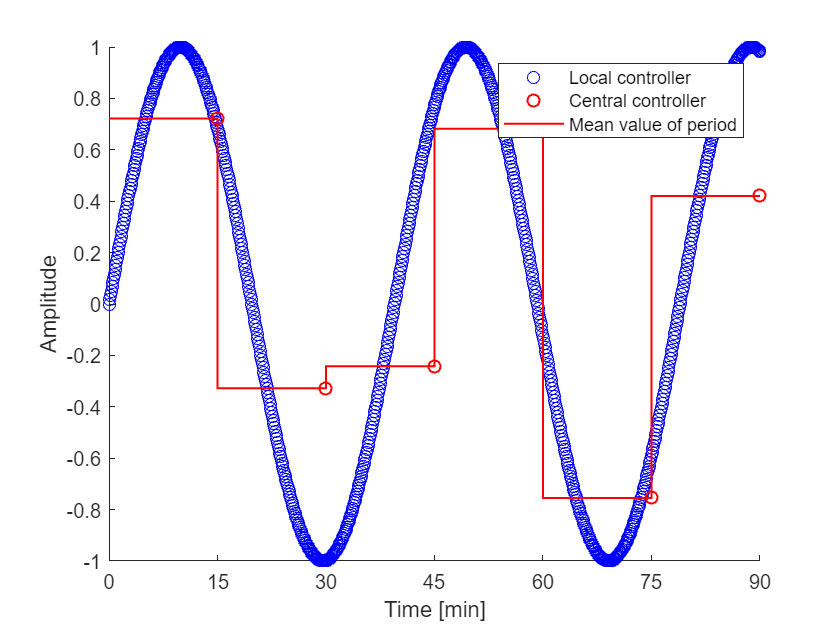

clc
clear
samples_local = 6;
samples_pr_period = 143;
samples_total = samples_local * samples_pr_period;

x_local = linspace(0,90,samples_total);
x_central = linspace(15,90,samples_local);

y_local = sin(x_local/(2*pi));

y_central = zeros(1,6);
for i=1:samples_local
    y_central(i) = sum(y_local((i-1)*samples_pr_period + 1:i*samples_pr_period))/samples_pr_period;
end

figure()
hold on
l1=plot(x_local,y_local, 'o',Color='blue');
l2=plot(x_central, y_central, 'o', Color='red' ,LineWidth=1);
l3=stairs([0 x_central],[y_central y_central(end)], Color='red', LineWidth=1);
xticks((0:15:90))
xlim([0 90]);
ylabel("Amplitude")
xlabel("Time [min]")
legend("Local controller", "Central controller", "Mean value of period");
hold off
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/SpeedComparison','epsc')

## Impact of old dat

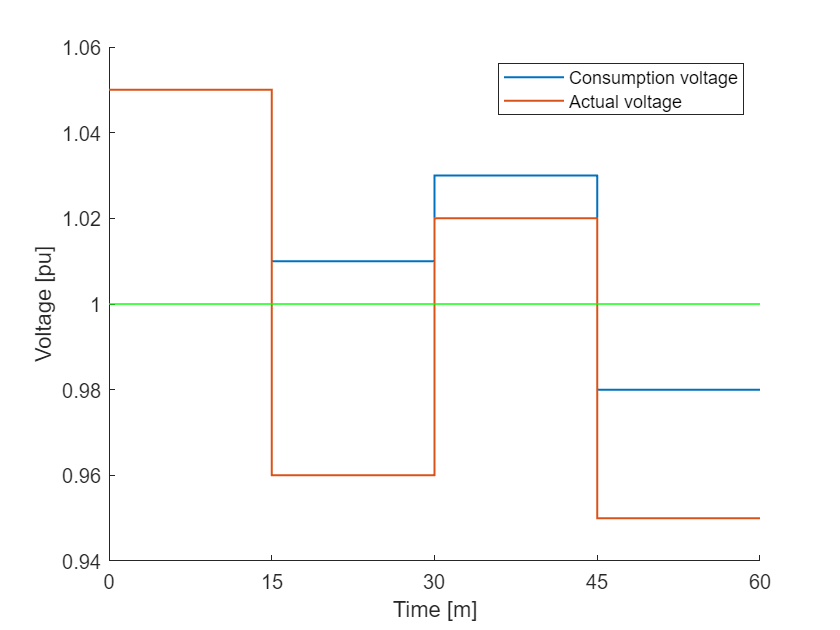

clc
clear
Vout = [1.05 ; 1.01 ; 1.03 ; .98;.98];
Vtrue = [1.05 ; 0.96 ; 1.02; .95 ; .95];
t = linspace(0,60,5);
figure()
hold on
stairs(t,Vout,LineWidth=1)
stairs(t,Vtrue, LineWidth=1)
yline(1, LineWidth=1, Color=[0,1,0])
hold off
ylim([0.94 ; 1.06])
xticks([0, 15, 30, 45, 60])
xlabel("Time [m]")
ylabel("Voltage [pu]")
legend("Consumption voltage", "Actual voltage")
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/ImpactOfOldData','epsc')

## Linearisation

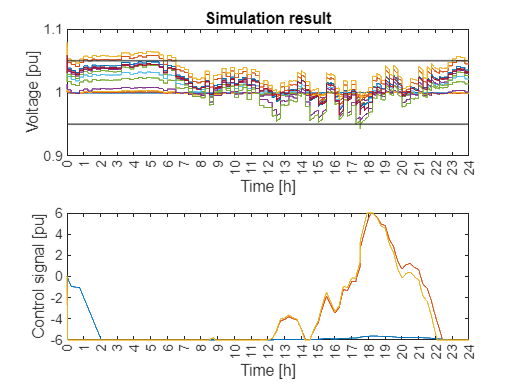

clc
clear
load("SimulationResultNoNoise.mat")
load("DataAndVariables\AvgValues.mat")
uMax = 6;
t = linspace(0,24,length(x));
figure()
subplot(2,1,1)
plot(t,(x+V0(15:end))')
yline(0.95, LineWidth=1)
yline(1.05, LineWidth=1)
title("Simulation result") % using linearisation at each step
ylabel("Voltage [pu]")
xlabel("Time [h]")
ylim([0.9,1.1])
xlim([0,24])
xticks(0:1:24)
subplot(2,1,2)
plot(t,u')
ylabel("Control signal [pu]")
xlabel("Time [h]")
ylim([-uMax,uMax])
yticks(-uMax:2:uMax)
xlim([0,24])
xticks(0:1:24)
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/SimRes','epsc')

## Step Linearisation

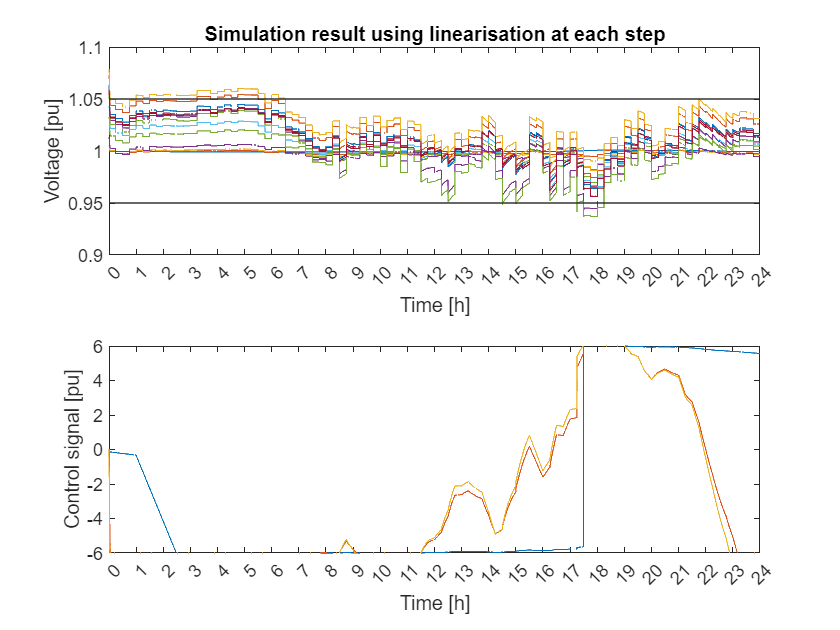

clc
clear
load("LinearisedSimulationResultNoNoise.mat")
load("DataAndVariables\AvgValues.mat")
uMax = 6;
t = linspace(0,24,length(x));
figure()
subplot(2,1,1)
plot(t,(x+VlinPlot)')
yline(0.95, LineWidth=1)
yline(1.05, LineWidth=1)
title("Simulation result using linearisation at each step") % using linearisation at each step
ylabel("Voltage [pu]")
xlabel("Time [h]")
ylim([0.9,1.1])
xlim([0,24])
xticks(0:1:24)
subplot(2,1,2)
plot(t,u')
ylabel("Control signal [pu]")
xlabel("Time [h]")
ylim([-uMax,uMax])
yticks(-uMax:2:uMax)
xlim([0,24])
xticks(0:1:24)
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/SimResStepLin','epsc')

## Comparison

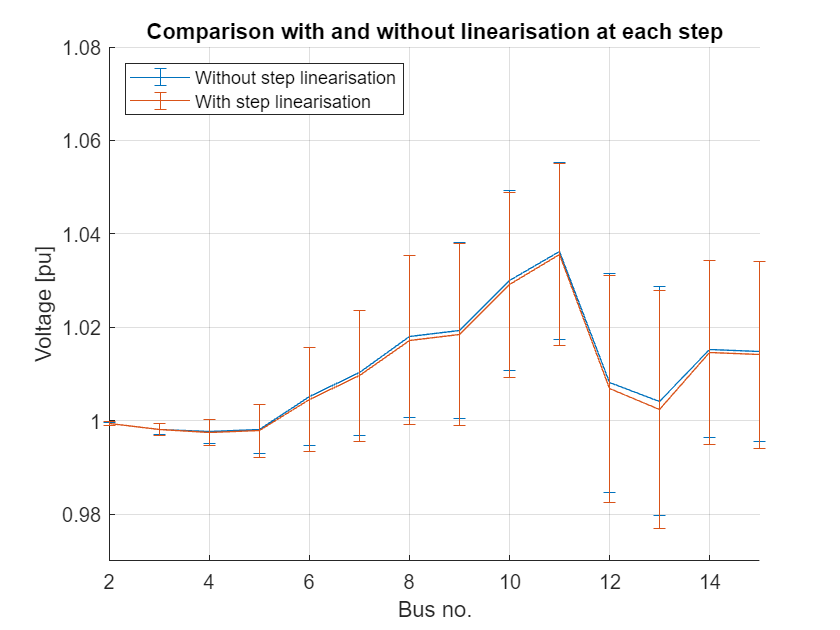

clc
clear
uMax = 6;
load("DataAndVariables\AvgValues.mat")
load("BackupData\SimulationResultNoise.mat")
MeanVal(:,1) = mean(x,2) + V0(15:end);
VarVal(:,1) = var(x');
load("BackupData\LinearisedSimulationResultNoise.mat")
MeanVal(:,2) = mean(x+VlinPlot,2);
VarVal(:,2) = var((x+VlinPlot)');

busNo = linspace(2,15,14);
figure()
hold on
errorbar(busNo,MeanVal(:,1),sqrt(VarVal(:,1)))
errorbar(busNo,MeanVal(:,2),sqrt(VarVal(:,2)))
xlim([2 15])
ylim([0.97 1.08])
xlabel("Bus no.")
ylabel("Voltage [pu]")
title("Comparison with and without linearisation at each step")
legend("Without step linearisation","With step linearisation",Location="northwest")
hold off
grid on
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/Comparison_Linearisation','epsc')